# Assignment 3 - Question 5 - Reza Mansouri - 002784647

## Step 1: Read Images

Read the reference image containing the object of interest.

boxImage = imread('./input/5_object.jpg');
sceneImage = imread('./input/5_frame_15.jpg');

## Step 2: Detect Point Features

Detect point features in both images.

boxPoints = detectSURFFeatures(boxImage);
scenePoints = detectSURFFeatures(sceneImage);

## Step 3: Extract Feature Descriptors

Extract feature descriptors at the interest points in both images.

[boxFeatures, boxPoints] = extractFeatures(boxImage, boxPoints);
[sceneFeatures, scenePoints] = extractFeatures(sceneImage, scenePoints);

## Step 4: Find Putative Point Matches

Match the features using their descriptors.

boxPairs = matchFeatures(boxFeatures, sceneFeatures);

Display putatively matched features.

matchedBoxPoints = boxPoints(boxPairs(:, 1), :);
matchedScenePoints = scenePoints(boxPairs(:, 2), :);
figure;
showMatchedFeatures(boxImage, sceneImage, matchedBoxPoints, ...
    matchedScenePoints, 'montage');
title('Putatively Matched Points (Including Outliers)');

## Step 5: Locate the Object in the Scene Using Putative Matches

[tform, inlierIdx] = estgeotform2d(matchedBoxPoints, matchedScenePoints, 'affine');
inlierBoxPoints   = matchedBoxPoints(inlierIdx, :);
inlierScenePoints = matchedScenePoints(inlierIdx, :);

Get the bounding polygon of the reference image.

boxPolygon = [1, 1;...                           % top-left
    size(boxImage, 2), 1;...                 % top-right
    size(boxImage, 2), size(boxImage, 1);... % bottom-right
    1, size(boxImage, 1);...                 % bottom-left
    1, 1];                   % top-left again to close the polygon

Transform the polygon into the coordinate system of the target image. The transformed polygon indicates the location of the object in the scene.

newBoxPolygon = transformPointsForward(tform, boxPolygon);

Display the detected object.

figure;
imshow(sceneImage);
hold on;
line(newBoxPolygon(:, 1), newBoxPolygon(:, 2), Color='y');
title('Detected Box');

## Step 6: Doing the same for 9 other random frames

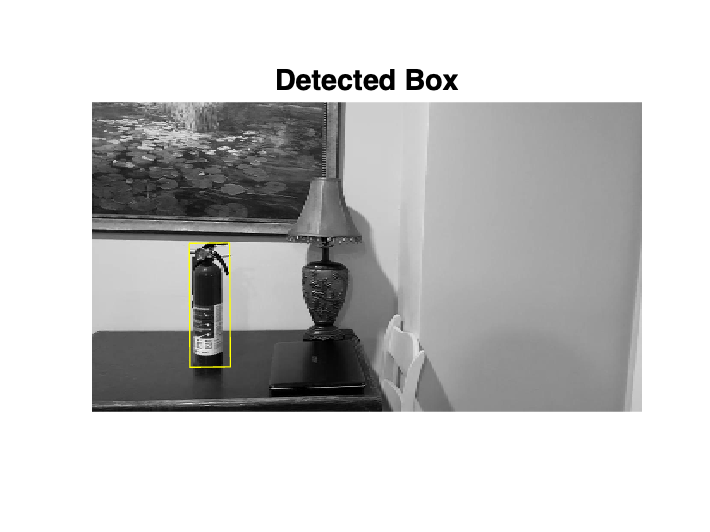

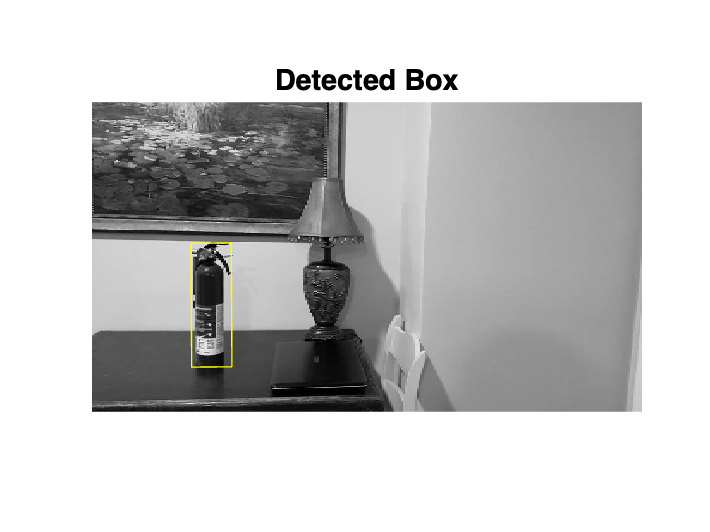

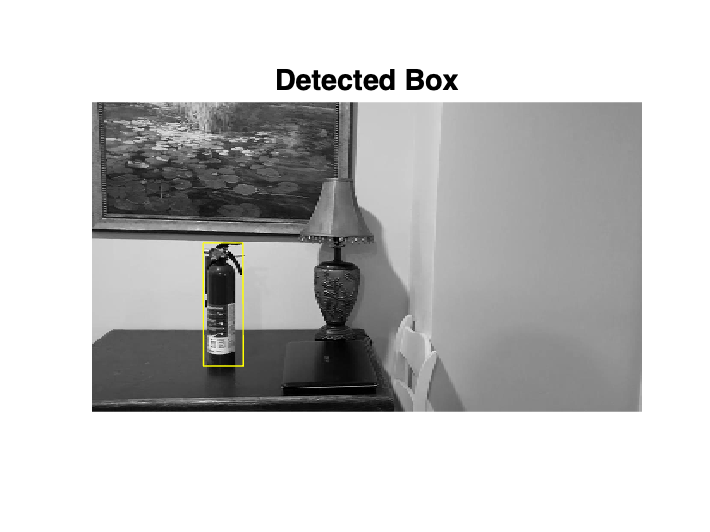

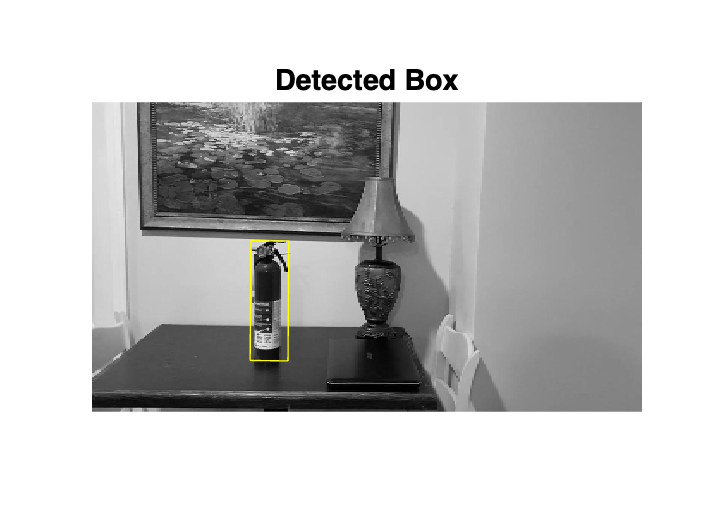

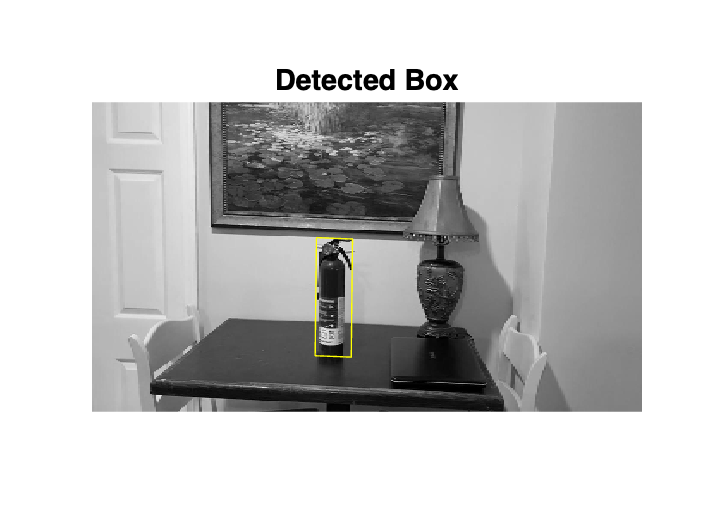

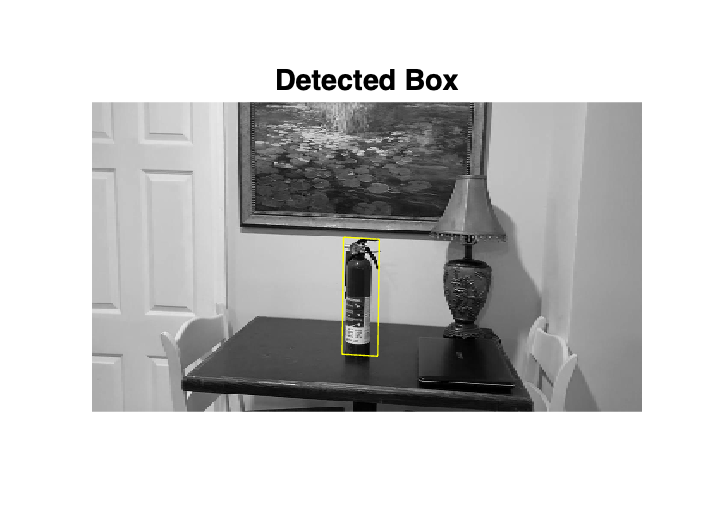

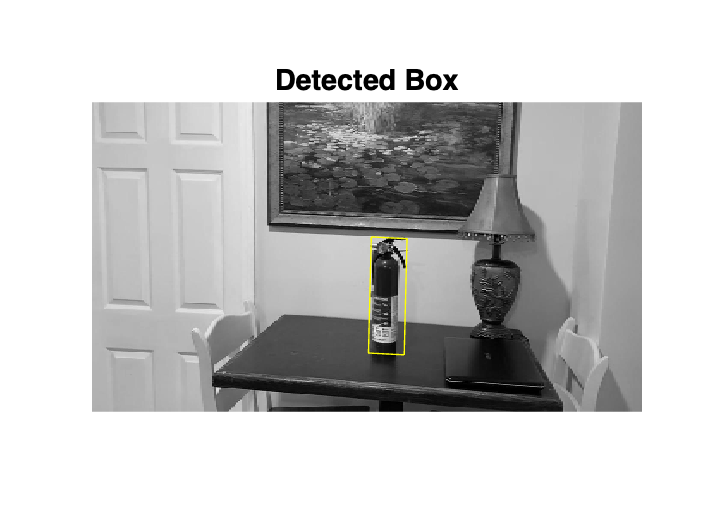

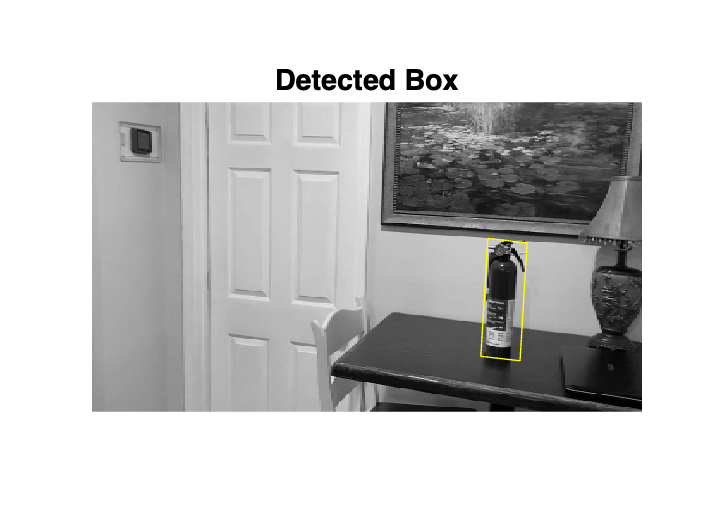

paths = ["./input/5_frame_84.jpg","./input/5_frame_85.jpg","./input/5_frame_92.jpg","./input/5_frame_119.jpg","./input/5_frame_163.jpg","./input/5_frame_181.jpg","./input/5_frame_199.jpg","./input/5_frame_267.jpg","./input/5_frame_155.jpg"];
for i=1:numel(paths)
    sceneImage = imread(paths(i));
    scenePoints = detectSURFFeatures(sceneImage);

    [sceneFeatures, scenePoints] = extractFeatures(sceneImage, scenePoints);

    boxPairs = matchFeatures(boxFeatures, sceneFeatures);

    matchedBoxPoints = boxPoints(boxPairs(:, 1), :);
    matchedScenePoints = scenePoints(boxPairs(:, 2), :);

    [tform, inlierIdx] = estgeotform2d(matchedBoxPoints, matchedScenePoints, 'affine');

    boxPolygon = [1, 1;...
    size(boxImage, 2), 1;...
    size(boxImage, 2), size(boxImage, 1);...
    1, size(boxImage, 1);...
    1, 1];
    newBoxPolygon = transformPointsForward(tform, boxPolygon);

    figure;
    imshow(sceneImage);
    hold on;
    line(newBoxPolygon(:, 1), newBoxPolygon(:, 2), Color='y');
    title('Detected Box');
end